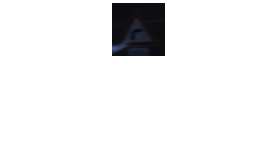

I = readimg(20, 8, 25);
imshow(I);


[height, width, ~] = size(I)

height = 53

width = 159

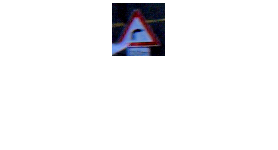


I = preprocess(I);
imshow(I);

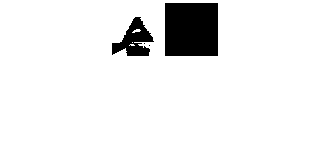


colors = splitColor(I);

R = colors(:,:,1);

width = size(I,2);

BK = colors(:,:,4);
W = preprocessChannel(colors(:,:,5));

imshowpair(BK,W,'montage');


[centre, radi] = imfindcircles(W,[5,20]);

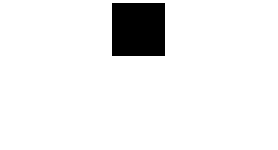


if (size(centre,1) > 0)
    imagesize = size(I);
    [xx,yy] = ndgrid((1:imagesize(1))-centre(2),(1:imagesize(2))-centre(1));
    mask = uint8((xx.^2 + yy.^2)<(radi^2));
end

imshow(W);

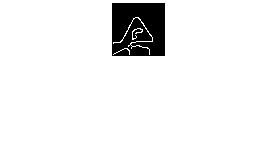


R = colors(:,:,1);

W = colors(:,:,5);

WE = edge(W,'canny');

imshow(WE);


[H,theta,rho] = hough(WE);
% P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
P = houghpeaks(H,5);
lines = houghlines(WE,theta,rho,P,'FillGap',width/7,'MinLength',width/2.5)

lines = 1×4 struct array with fields:
    point1
    point2
    theta
    rho


p1 = struct2table(lines).point1

p1 =     22    16
    27    15
    27    15
    24    15


p2 = struct2table(lines).point2

p2 =     10    39
    41    36
    41    37
     9    40



Pch = [p1;p2]

Pch =     22    16
    27    15
    27    15
    24    15
    10    39
    41    36
    41    37
     9    40



k = convhull(Pch)

k =      1
     4
     2
     6
     7
     8
     1



X = Pch(k,1)

X =     22
    24
    27
    41
    41
     9
    22


Y = Pch(k,2)

Y =     16
    15
    15
    36
    37
    40
    16


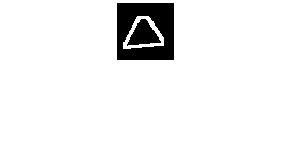


mask2 = poly2mask(X,Y,size(I,1),size(I,2));

hold off

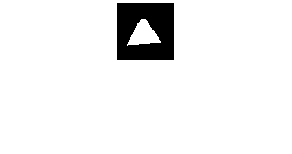

imshow(mask2);

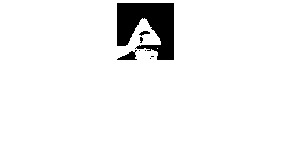

imshow(W);

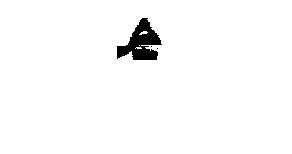

imshow(BK);

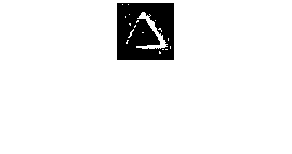


imshow(R);

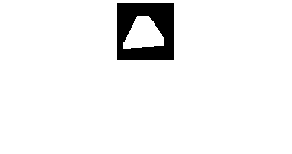



newW = mask2 & W & ~BK;

aux = imdilate(newW, ones(int8(width/8)));

imshow(aux);


imshow(aux & ~mask2);

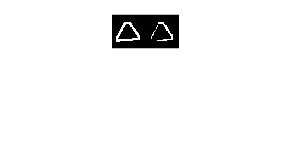


border = aux & ~mask2;

border2 = border & R;

imshowpair(border, border2, 'montage');


bs = sum(sum(border))

bs = 367

bs2 = sum(sum(border2))

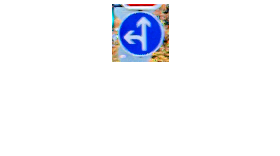

I = readimg(37,1,20);

I = preprocess(I);

imshow(I);

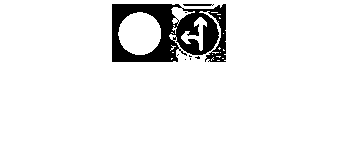


colors = splitColor(I);
W = colors(:,:,5);
R = colors(:,:,1);
B = colors(:,:,2);

BK = colors(:,:,4);

maskW = descriptors(W);
maskR = descriptors(R);
maskB = descriptors(B);

imshowpair(maskB,W, 'montage');

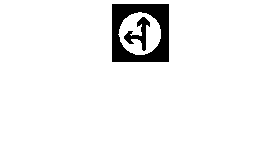


BW = maskB & ~W;

imshow(BW);